Bewegungsgleichung:

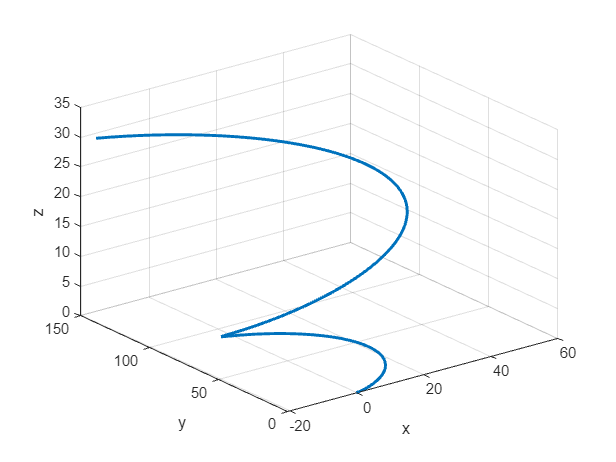

R_0 = [0; 0; 0];
V_0 = [0; 0; 0];
t = linspace(0, 20, 200);
A = [5 * cos(t/2); 5 * sin(t/2); 0.2 * ones(size(t/2))]; % Erhöhte Beschleunigung
V = cumtrapz(t/2, A, 2) + V_0;

R = R_0 + cumtrapz(t/2, V, 2) + 0.5 * cumtrapz(t/2, A, 2) .* t;

figure;
plot3(R(1,:), R(2,:), R(3,:), 'LineWidth', 2);
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

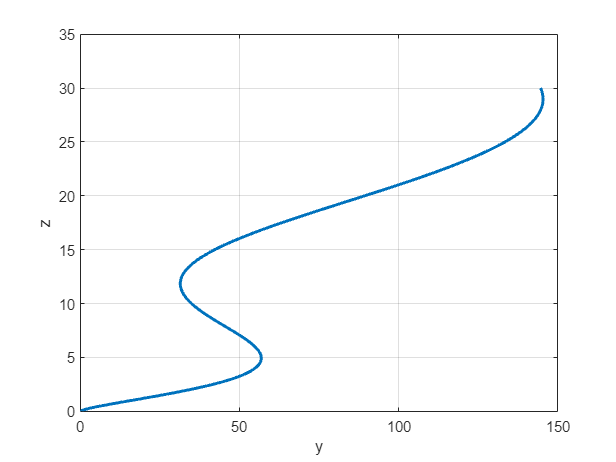

figure(1);
plot(R(2,:), R(3,:), 'LineWidth', 2);
ylabel('z');
xlabel('y');
grid on;

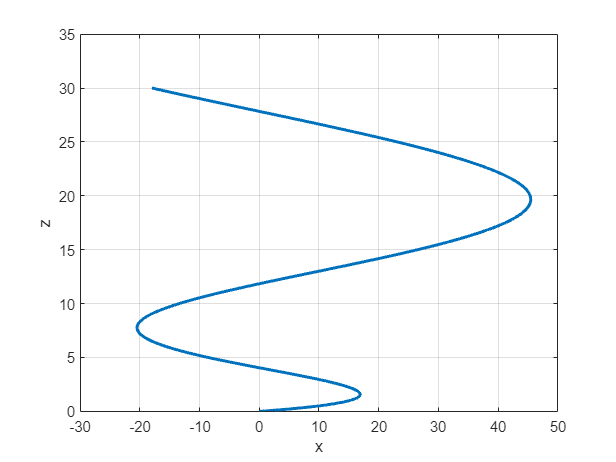


figure(2);
plot(R(1,:), R(3,:), 'LineWidth', 2);
ylabel('z');
xlabel('x');
grid on;

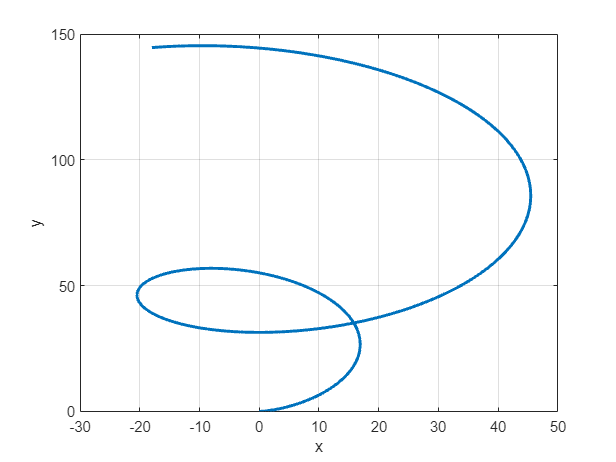


figure(3);
plot(R(1,:), R(2,:), 'LineWidth', 2);
ylabel('y');
xlabel('x');
grid on;

Gemessene Werte:

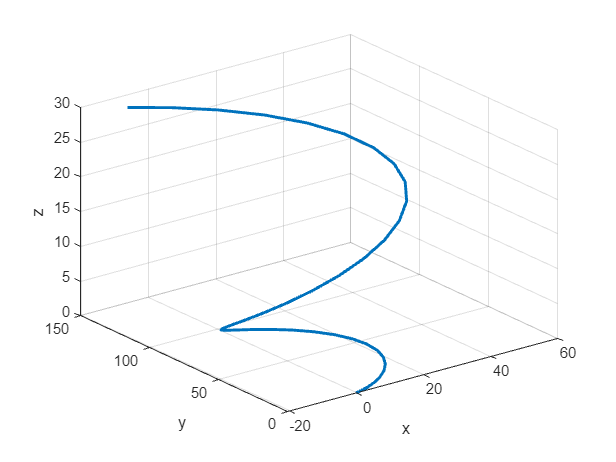

R_measured = extract_every_third_column(R);
figure;
plot3(R_measured(1,:), R_measured(2,:), R_measured(3,:), 'LineWidth', 2);
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

% y = awgn(R_measured,5);
% 
% figure;
% plot3(y(1,:), y(2,:), y(3,:), 'LineWidth', 2);
% xlabel('x');
% ylabel('y');
% zlabel('z');
% grid on;


R_measured(3,:)

ans =          0    0.0189    0.0758    0.1705    0.3030    0.4735    0.6818    0.9280    1.2121    1.5341    1.8939    2.2916    2.7272    3.2007    3.7120    4.2613    4.8484    5.4733    6.1362    6.8369    7.5756    8.3521    9.1664   10.0187   10.9088   11.8368   12.8027   13.8065   14.8481   15.9276   17.0450   18.2003   19.3934   20.6245   21.8934   23.2002   24.5448   25.9274   27.3478   28.8061


for i=1:length(R_measured(3,:))
    % Zufällige Werte zwischen -2 und 2 generieren
    randomValues = 4 * rand(1, 1) - 2;
    R_measured(3,i) = R_measured(3,i) + randomValues;
end
R_measured(3,:)

ans =     1.2869   -0.2614    1.6268   -0.2648    1.3795    0.0606    1.9159    1.9483    0.7217    0.3981    3.0555    4.0888    2.0375    3.8857    3.4666    5.5953    5.9238    4.1424    7.5841    8.7964    7.6333    9.8892    9.5185    8.6377    9.7083   11.4646   13.7975   15.1088   16.0080   15.2017   17.1813   16.5601   17.8403   19.1696   22.6080   23.1809   23.3037   25.9074   25.9382   27.0260


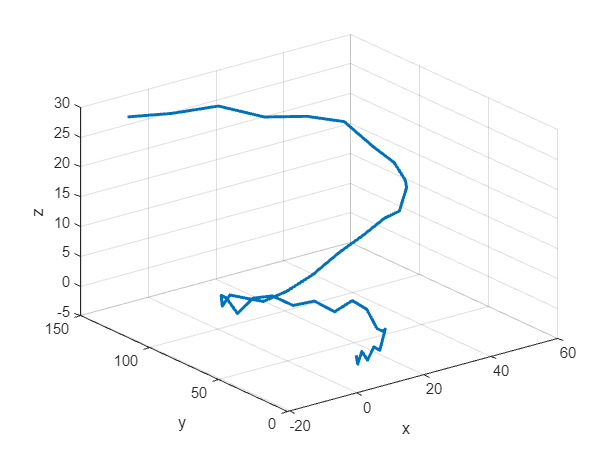

figure;
plot3(R_measured(1,:), R_measured(2,:), R_measured(3,:), 'LineWidth', 2);
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

% Gegebene 3D-Punkte (X, Y, Z)
% R_measured = 3x20
points = transpose(R_measured)

points =          0         0    1.2869
    0.4692    0.0529   -0.2614
    1.8277    0.4155    1.6268
    3.9327    1.3682   -0.2648
    6.5599    3.1358    1.3795
    9.4238    5.8647    0.0606
   12.2030    9.6079    1.9159
   14.5692   14.3176    1.9483
   16.2176   19.8459    0.7217
   16.8958   25.9553    0.3981



% Zeitpunkte für die Punkte (optional)
% t = 1x200
t_measured = extract_every_third_column(t)

t_measured =          0    0.5025    1.0050    1.5075    2.0101    2.5126    3.0151    3.5176    4.0201    4.5226    5.0251    5.5276    6.0302    6.5327    7.0352    7.5377    8.0402    8.5427    9.0452    9.5477   10.0503   10.5528   11.0553   11.5578   12.0603   12.5628   13.0653   13.5678   14.0704   14.5729   15.0754   15.5779   16.0804   16.5829   17.0854   17.5879   18.0905   18.5930   19.0955   19.5980


% time = 20x1
time = transpose(t_measured)

time =          0
    0.5025
    1.0050
    1.5075
    2.0101
    2.5126
    3.0151
    3.5176
    4.0201
    4.5226




% Berechnung der Geschwindigkeit
velocityX = diff(points(:, 1)) ./ diff(time);
velocityY = diff(points(:, 2)) ./ diff(time);
velocityZ = diff(points(:, 3)) ./ diff(time);

% Geschwindigkeitsvektor erstellen
% velocityVector = [VX1, VY1, VZ1;
%                   VX2, VY2, VZ2;
%                   VX3, VY3, VZ3;
%                   ...];
velocityVector = [velocityX, velocityY, velocityZ];

% Berechnung der Beschleunigung
accelerationX = diff(velocityVector(:, 1)) ./ diff(time(1:end-1));
accelerationY = diff(velocityVector(:, 2)) ./ diff(time(1:end-1));
accelerationZ = diff(velocityVector(:, 3)) ./ diff(time(1:end-1));

% Beschleunigungsvektor erstellen
accelerationVector = [accelerationX, accelerationY, accelerationZ];


% Ergebnis ausgeben
disp(velocityVector);

    0.9337    0.1052   -3.0810
    2.7035    0.7215    3.7575
    4.1888    1.8961   -3.7644
    5.2281    3.5174    3.2722
    5.6992    5.4304   -2.6245
    5.5306    7.4490    3.6919
    4.7087    9.3723    0.0646
    3.2803   11.0014   -2.4410
    1.3497   12.1576   -0.6439
   -0.9288   12.6975    5.2882
   -3.3623   12.5270    2.0563
   -5.7349   11.6109   -4.0822
   -7.8250    9.9781    3.6781
   -9.4241    7.7211   -0.8341
  -10.3542    4.9914    4.2360
  -10.4842    1.9891    0.6538
   -9.7430   -1.0515   -3.5450
   -8.1271   -3.8792    6.8491
   -5.7047   -6.2461    2.4125
   -2.6133   -7.9268   -2.3147
    0.9482   -8.7378    4.4893
    4.7322   -8.5539   -0.7376
    8.4593   -7.3209   -1.7529
   11.8386   -5.0624    2.1304
   14.5896   -1.8828    3.4952
   16.4640    2.0380    4.6424
   17.2660    6.4537    2.6094
   16.8697   11.0679    1.7893
   15.2313   15.5533   -1.6044
   12.3969   19.5749    3.9393
    8.5025   22.8144   -1.2361
    3.7683   24.9941    2.5475
   -1.51

% Ergebnis ausgeben
disp(accelerationVector);

    3.5218    1.2265   13.6088
    2.9559    2.3373  -14.9687
    2.0682    3.2265   14.0027
    0.9374    3.8069  -11.7343
   -0.3356    4.0170   12.5696
   -1.6355    3.8272   -7.2183
   -2.8425    3.2421   -4.9862
   -3.8420    2.3007    3.5764
   -4.5342    1.0743   11.8048
   -4.8427   -0.3393   -6.4316
   -4.7215   -1.8229  -12.2156
   -4.1594   -3.2494   15.4429
   -3.1821   -4.4914   -8.9791
   -1.8508   -5.4321   10.0895
   -0.2588   -5.9746   -7.1287
    1.4751   -6.0507   -8.3556
    3.2156   -5.6273   20.6843
    4.8204   -4.7101   -8.8289
    6.1519   -3.3445   -9.4072
    7.0874   -1.6139   13.5400
    7.5301    0.3658  -10.4015
    7.4169    2.4538   -2.0204
    6.7249    4.4943    7.7278
    5.4745    6.3275    2.7159
    3.7301    7.8023    2.2831
    1.5960    8.7873   -4.0457
   -0.7888    9.1822   -1.6320
   -3.2603    8.9259   -6.7535
   -5.6405    8.0030   11.0320
   -7.7499    6.4465  -10.2992
   -9.4210    4.3376    7.5295
  -10.5106    1.8013    0.1949
  -10.91

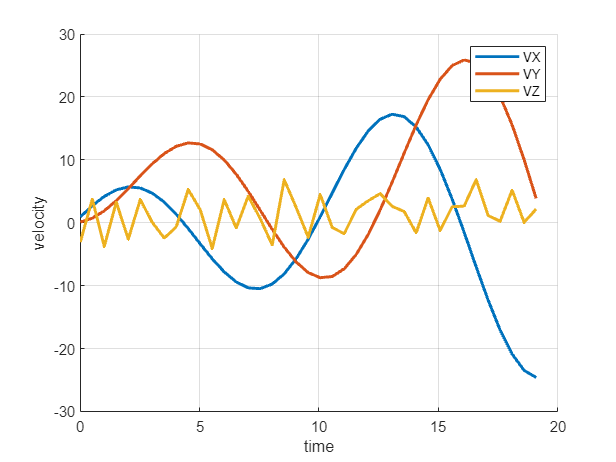

velocityVector = transpose(velocityVector);
time = transpose(time(1:end-1));

figure;
hold on;

plot(time, velocityVector(1,:), 'LineWidth', 2);
plot(time, velocityVector(2,:), 'LineWidth', 2);
plot(time, velocityVector(3,:), 'LineWidth', 2);

xlabel('time');
ylabel('velocity');
grid on;

legend('VX', 'VY', 'VZ');

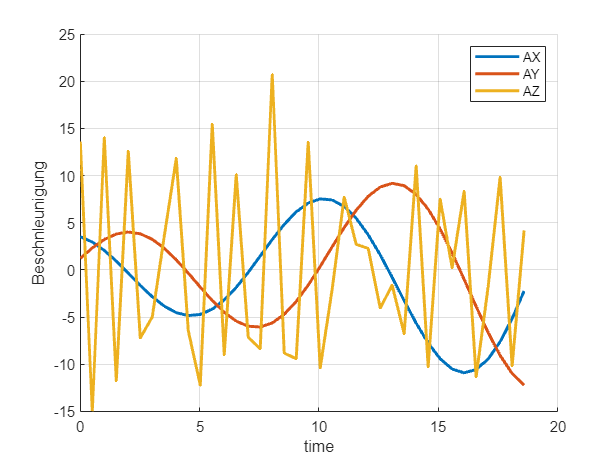

accelerationVector = transpose(accelerationVector);
time = transpose(time(1:end-1));

figure;
hold on;

plot(time, accelerationVector(1,:), 'LineWidth', 2);
plot(time, accelerationVector(2,:), 'LineWidth', 2);
plot(time, accelerationVector(3,:), 'LineWidth', 2);

xlabel('time');
ylabel('Beschnleunigung');
grid on;

legend('AX', 'AY', 'AZ');

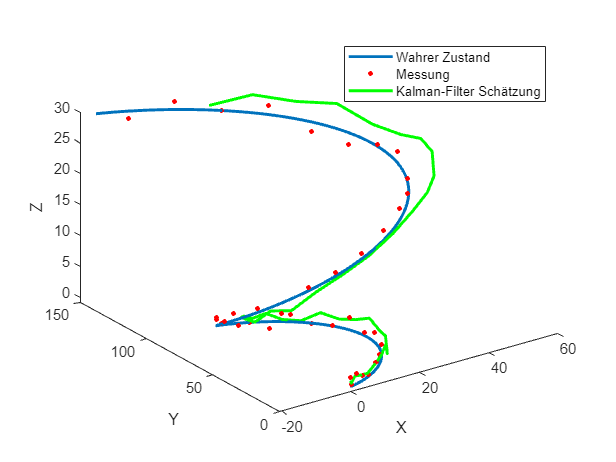

% Gegebenes Beispiel
R_0 = [0; 0; 0];
V_0 = [0; 0; 0];
t = linspace(0, 20, 200);
A = [5 * cos(t/2); 5 * sin(t/2); 0.2 * ones(size(t/2))]; % Erhöhte Beschleunigung
V = cumtrapz(t/2, A, 2) + V_0;

R = R_0 + cumtrapz(t/2, V, 2) + 0.5 * cumtrapz(t/2, A, 2) .* t;

R_measured = extract_every_third_column(R);
for i=1:length(R_measured(3,:))
    % Zufällige Werte zwischen -2 und 2 generieren
    randomValues = 4 * rand(1, 1) - 2;
    R_measured(3,i) = R_measured(3,i) + randomValues;
end

% Kalman-Filter Parameter
dt = 0.5;                % Abtastzeit
A_kalman = [1 dt dt^2/2; 0 1 dt; 0 0 1];       % Zustandsübergangsmatrix
B_kalman = [dt^3/6; dt^2/2; dt];               % Steuerungsmatrix (Beschleunigung)
C_kalman = eye(3);                             % Messmatrix (direkte Messung von X, Y, Z)
Q_kalman = diag([0.8, 0.8, 0.8]);              % Prozessrauschkovarianz
R_kalman = diag([0.3, 0.5, 0.5]);              % Messrauschkovarianz

% Initialisierung
x_kalman = zeros(3, length(R_measured));
P_kalman = zeros(3, 3, length(R_measured));

% Schätzung mit Kalman-Filter
for i = 1:length(R_measured)
    % Vorhersage
    if i == 1
        x_pred = [0; 0; 0];
        P_pred = eye(3);
    else
        x_pred = A_kalman * x_kalman(:, i-1) + B_kalman .* A(:, i-1);
        P_pred = A_kalman * P_kalman(:, :, i-1) * A_kalman' + Q_kalman;
    end
    
    % Korrektur
    K = P_pred * C_kalman' / (C_kalman * P_pred * C_kalman' + R_kalman);
    x_kalman(:, i) = x_pred + K * (R_measured(:, i) - C_kalman * x_pred);
    P_kalman(:, :, i) = (eye(3) - K * C_kalman) * P_pred;
end

% Ergebnisse anzeigen
figure;
hold on;
plot3(R(1,:), R(2,:), R(3,:), 'LineWidth', 2);
plot3(R_measured(1,:), R_measured(2,:), R_measured(3,:), 'r.', 'MarkerSize', 10);
plot3(x_kalman(1,:), x_kalman(2,:), x_kalman(3,:), 'g-', 'LineWidth', 2);
legend('Wahrer Zustand', 'Messung', 'Kalman-Filter Schätzung');
xlabel('X');
ylabel('Y');
zlabel('Z');
view(3);

function new_array = extract_every_third_column(R)
    new_array = R(:, 1:5:end);
end